clear
close all
savefig=0;

## data reading - ROI color extraction

path = 'E:\Data\Aurelie\data\nocues\444119\220919_plane0\';

[red, red890, green, blue,calcium] = data_read_extraction (path);%RGB intensities of RGB channels for each ROI


[aligned_red, aligned_green, aligned_blue, calcium_norm] = image_processing(red, red890, green, blue,calcium);%motioncorrection-background substraction


[roi_red,roi_green,roi_blue,roi_ca] = ROI_extraction (path,aligned_red, aligned_green, aligned_blue,calcium_norm);


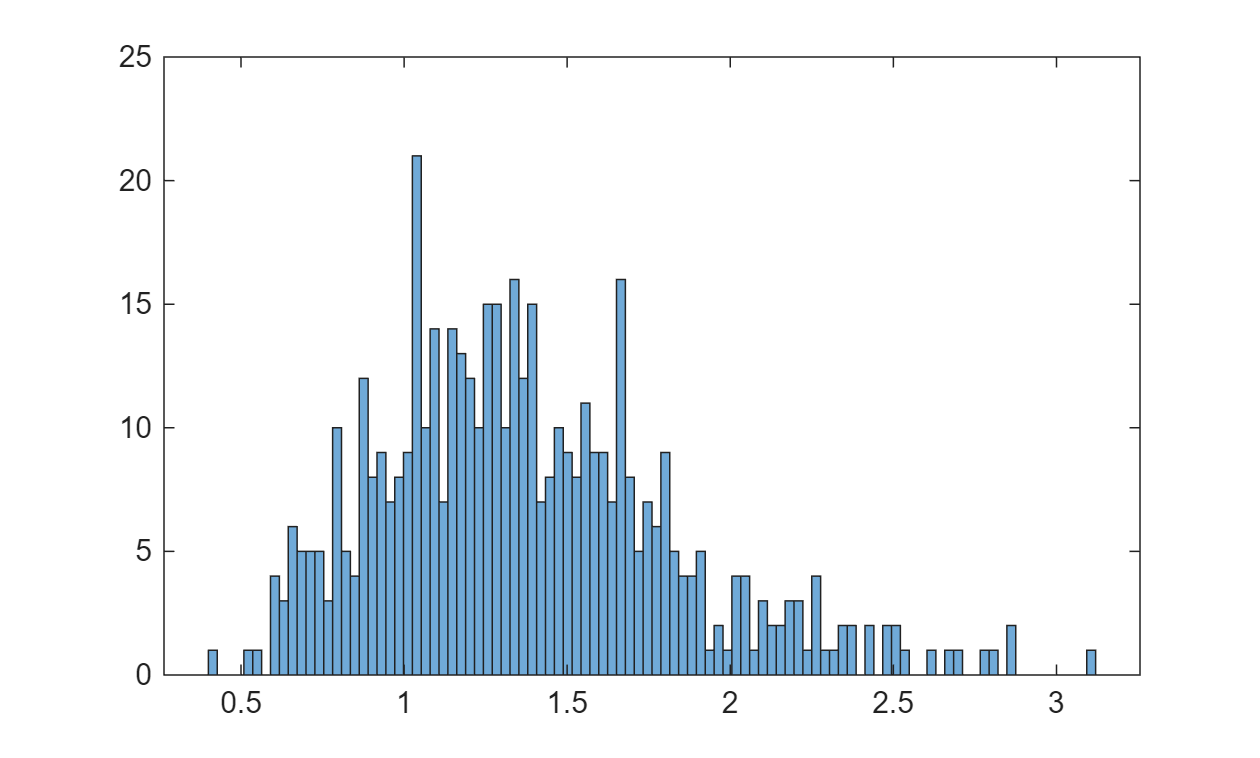

k_estime = 1

==== RÉSULTAT ====
Le pic est exactement à : 1.0000
La fuite du GCaMP dans le YFP est de : 100.0 %



[YFP_corrige,k_estime,ratio] = bleedthrough_correction (roi_green,roi_ca);

% figure;histogram (ratio_YFP_GCaMP,50)

%calcul green_deconv

% [red, green, blue,calcium,YFP_corrige,NCell, R, Y, B, Ca] = data_read_extraction (path,1,k_estime);


## calcul ratio / unmixing

% methode 1 min max
[Donnees_Clustering,r,g,b] = minmax (R,Y,B,Ca,k_estime);
% % methode 2 linear unmixing
% [Donnees_Clustering, r,g, b] = linear_unmixing (R, YFP_corrige, B); %rgb: demixed normalised RGB intensities
% [Donnees_Clustering, r,g, b] = linear_unmixing (R, Y, B); %rgb: demixed normalised RGB intensities
if savefig == 1
    namegraph=strcat(namefull,['Maxwell_unmixed' , '.png']);
    exportgraphics(gcf,namegraph,'Resolution',150,'BackgroundColor','black')
    close gcf
end
%all=[r,g,b];

## clustering

% idx_cluster = geometrique_class (Donnees_Clustering);
%gmm brainbow proportion clustering
% [idx_cluster,Ycat_gmm_priors] = GMM_proportion (Donnees_Clustering);
% Ycat_hybride = hybrid_clustering (Donnees_Clustering);
% Ycat_hybride_pond = hybrid_KNN_clustering (Donnees_Clustering);
% colorcell_hybrid = hybrid_KNN_clustering_weighted (Donnees_Clustering);
% colorcell_dominance = dominance_clustering (Donnees_Clustering,NCell,r,g,b);
% Épaisseur de la bande noire (0.02 = environ 2% d'incertitude)
% Augmentez à 0.03 ou 0.04 si la bande est trop fine.
ep = 0.02; 

colorcell_classification = color_classification (Donnees_Clustering, NCell, r, g, b, ep);
triangle_maxwell (colorcell_classification,Donnees_Clustering,0)
%sum(colorcell_classification==8)

if savefig == 1
    namegraph=strcat(namefull,['Maxwell_color_dominance_classification' , '.png']);
    exportgraphics(gcf,namegraph,'Resolution',150,'BackgroundColor','black')
    close gcf
end
%% removal dark ROI and small cells or the one with too much variability
[colorcell_corrected,id_low_intensity ]  = removal_low_intensities (colorcell_classification,NCell,R,Y,B,10);
colorcell = colorcell_corrected;
%sum(colorcell==8)
%save colorcell

%save (strcat(path,'colorcell_Maxwell'),"colorcell")
% sauvegarder_mosaique_cellule(id_low_intensity, Volume_Utile, X_pts, Y_pts, Z_pts, z_min_utile, rgb_cellule, dossier_sortie);
triangle_maxwell (colorcell,Donnees_Clustering,0)
if savefig == 1
    namegraph=strcat(namefull,['Maxwell_color_dominance_classification_black' , '.png']);
    exportgraphics(gcf,namegraph,'Resolution',150,'BackgroundColor','black')
    close gcf
end

proportion(colorcell)
%save info color in excel
%save_excel(k_estime)

%triangle de Maxwell avec exvivo colorcell
% load("E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_validatedprediction_20260507.mat")
% triangle_maxwell (colorcell,Donnees_Clustering,0,id_low_intensity)



%consensus matrix
% load("E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_invivo_20260424.mat");

colorcell_method1 = uint8(colorcell_corrected);
% 
% load("E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcellnew.mat");
load("E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_validatedprediction_20260507.mat");
colorcell_method2 = uint8(colorcell);
write_number=1; %write_number on maxwell triangle
confusion_matrix (colorcell_method1,colorcell_method2,Donnees_Clustering,R,Y,B,write_number);
affichage (colorcell_method1,colorcell_method2,Donnees_Clustering,write_number)


function [red, red890,green, blue, calcium] = data_read_extraction (path)

blue=double(imread([path,'blue_new.tif']));
red=double(imread([path,'red_new.tif']));
red890=double(imread([path,'red890_new.tif']));
green=double(imread([path,'green_new.tif']));
calcium=double(imread([path,'calcium.tif']));

end

function [R,G,B,Ca] = ROI_extraction  (path,aligned_red,aligned_green,aligned_blue,calcium_norm) 

load(fullfile(path, 'Fall.mat'),'stat','iscell');
% L'élément structurant pour l'érosion du masque de la cellule
se = strel('disk', 1);
[imgH,imgW ]= size (aligned_blue);
% 3. Pré-allocation (pour la rapidité)
NCell_total = sum(iscell(:,1) > 0);
meanBlue  = zeros(NCell_total, 1);
meanGreen = zeros(NCell_total, 1);
meanRed   = zeros(NCell_total, 1);
meanCalcium = zeros(NCell_total, 1);

% Variables cellules
outline_gcampx = cell(1, NCell_total);
outline_gcampy = cell(1, NCell_total);
neuropil = cell(1, NCell_total);
Coomasqx = cell(1, NCell_total);
Coomasqy = cell(1, NCell_total);

m = 0;

for n = 1 : length(stat)
    if iscell(n,1) == 1
        m = m + 1;
        % Extraction des données brutes (Suite2P est en Python 0-based -> MATLAB 1-based)
        outline_gcampx{m} = double(stat{1, n}.xext) + 1;
        outline_gcampy{m} = double(stat{1, n}.yext) + 1;
        neuropil{m} = stat{1, n}.neuropil_mask;
        
        xpix = double(stat{1, n}.xpix) + 1;
        ypix = double(stat{1, n}.ypix) + 1;
        
        % Sécurité : s'assurer qu'aucun pixel ne sort de l'image
        xpix = max(1, min(xpix, imgW));
        ypix = max(1, min(ypix, imgH));
        
        % --- ÉROSION CORRIGÉE ---
        % A. Convertir les coordonnées (x,y) en un index linéaire unique
        lin_idx = sub2ind([imgH, imgW], ypix, xpix);
        
        % B. Créer un masque vide, l'allumer aux coordonnées de la cellule, puis l'éroder
        mask = false(imgH, imgW);
        mask(lin_idx) = true;
        mask_eroded = imerode(mask, se);
        
        % C. Récupérer les nouveaux index après érosion
        eroded_idx = find(mask_eroded);
        
        % D. Sécurité : si la cellule était trop petite et a été entièrement effacée
        if isempty(eroded_idx)
            eroded_idx = lin_idx; % On garde l'originale
        end
        
        % Sauvegarde des nouvelles coordonnées X,Y érodées
        [new_y, new_x] = ind2sub([imgH, imgW], eroded_idx);
        Coomasqx{m} = new_x;
        Coomasqy{m} = new_y;
        
        % % --- NOUVEAUTÉ : "CORE PIXELS" ET CALCUL DE LA MÉDIANE ---
        % % On récupère les pixels sur l'image LISSÉE
        % pixels_B = blue_smooth(eroded_idx);
        % pixels_G = green_smooth(eroded_idx);
        % pixels_R = red_smooth(eroded_idx);
        % 
        % % Filtrage des 25% de pixels les plus sombres (bruit de fond restant)
        % if length(eroded_idx) >= 4 % S'il y a assez de pixels
        %     intensite_totale = pixels_B + pixels_G + pixels_R;
        %     seuil_bas = prctile(intensite_totale, 25);
        %     idx_core = (intensite_totale >= seuil_bas);
        % 
        %     % Calcul de la MEDIANE sur le "cœur" lumineux de la cellule
        %     meanBlue(m)  = median(pixels_B(idx_core));
        %     meanGreen(m) = median(pixels_G(idx_core));
        %     meanRed(m)   = median(pixels_R(idx_core));
        % else
        %     % Cellule minuscule : on prend juste la médiane globale
        %     meanBlue(m)  = median(pixels_B);
        %     meanGreen(m) = median(pixels_G);
        %     meanRed(m)   = median(pixels_R);
        % end
        meanBlue(m)  = median(aligned_blue(eroded_idx));
        meanGreen(m) = median(aligned_green(eroded_idx));
        meanRed(m)   = median(aligned_red(eroded_idx));
        meanCalcium(m)   = median(calcium_norm(eroded_idx));
    end
end

NCell = m;
% fprintf('Extraction terminée pour %d cellules.\n', NCell);

R = meanRed(1:NCell); % S'assurer de ne prendre que les cellules valides
G = meanGreen(1:NCell);
B = meanBlue(1:NCell);
Ca = meanCalcium (1:NCell);

% if nargin==3
%     YFP_corrige = G - (k * Ca);
% end
% 
% cutoff = 0.05 * prctile(YFP_corrige, 99);
% YFP_corrige(YFP_corrige < cutoff) = 0;

end


%%Methode1 min max robuste
function [Donnees_Clustering,r,g,b] = minmax (R,G,B,Ca,k)

% --- 1. NORMALISATION MIN-MAX ROBUSTE (Quantiles) ---
    p_low = 1; % Bruit de fond
    p_high = 99; % Intensité max robuste

    R_min = prctile(R, p_low); R_max = prctile(R, p_high);
    G_min = prctile(G, p_low); G_max = prctile(G, p_high);
    B_min = prctile(B, p_low); B_max = prctile(B, p_high);
    Ca_min = prctile(Ca, p_low); Ca_max = prctile(Ca, p_high);

    % On DOIT clipper entre 0 et 1 ici pour que l'heuristique fonctionne 
    % et pour éviter que des valeurs négatives ne faussent le ratio.
    R_norm = max(0, min(1, (R - R_min) ./ (R_max - R_min)));
    G_norm = max(0, min(1, (G - G_min) ./ (G_max - G_min)));
    B_norm = max(0, min(1, (B - B_min) ./ (B_max - B_min)));
    Ca_norm = max(0, min(1, (Ca - Ca_min) ./ (Ca_max - Ca_min)));

    % --- 2. CALCUL AUTOMATIQUE DU % DE FUITE (k_empirique) ---
    % On cible les cellules qui expriment fortement le GCaMP
    idx_high_Ca = Ca_norm > 0.5; 
    
    % Sécurité : si l'animal exprime très peu, on abaisse le critère
    if sum(idx_high_Ca) < 5
        idx_high_Ca = Ca_norm > 0.2;
    end

    % On calcule le ratio sur les données normalisées
    ratio_norm = G_norm(idx_high_Ca) ./ (Ca_norm(idx_high_Ca) + 0.001);

     G_corr_norm = G_norm - (k * Ca_norm);

    % Le "coup de hache" : on écrase tout le bruit négatif à zéro
    G_corr_norm(G_corr_norm < 0) = 0;

    % --- 4. CALCUL DES PROPORTIONS CHROMATIQUES ---
    % On utilise G_corr_norm à la place de G_norm
    Somme = R_norm + G_corr_norm + B_norm + 0.001;

    r = R_norm ./ Somme;
    g = G_corr_norm ./ Somme;
    b = B_norm ./ Somme;

    % --- 5. PROJECTION GÉOMÉTRIQUE DANS LE TRIANGLE 2D ---
    X_tri = r + (b * 0.5);
    Y_tri = b * (sqrt(3) / 2);
    
    Donnees_Clustering = [X_tri, Y_tri];

% % % --- 1. NORMALISATION MIN-MAX ROBUSTE (Quantiles) ---
% % p_low = 1;   % Bruit de fond
% % p_high = 99; % Intensité max robuste
% % 
% % R_min = prctile(R, p_low); R_max = prctile(R, p_high);
% % G_min = prctile(G, p_low); G_max = prctile(G, p_high);
% % B_min = prctile(B, p_low); B_max = prctile(B, p_high);
% % 
% % % Ici on ne clippe pas, tant pis si on dépasse (évite le bug des points superposés)
% % R_norm = (R - R_min) ./ (R_max - R_min);
% % G_norm = (G - G_min) ./ (G_max - G_min);
% % B_norm = (B - B_min) ./ (B_max - B_min);
% % 
% % % --- 2. Calcul des proportions chromatiques ---
% % Somme = abs(R_norm) + abs(G_norm) + abs(B_norm) + 0.001;
% % 
% % r = R_norm ./ Somme;
% % g = G_norm ./ Somme;
% % b = B_norm ./ Somme;
% % 
% % % --- 3. Projection géométrique dans le triangle 2D ---
% % X_tri = r + (b * 0.5);
% % Y_tri = b * (sqrt(3) / 2);

% --- 4. Dessin de la figure ---
figure('Name', 'Triangle de Maxwell Démixé', 'Color', 'w');
hold on;

plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

pas = 0.25;
for frac = pas:pas:1-pas
    text(frac, -0.04, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'center', 'Color', [0.6 0 0]);
    x_droit = 1 - (frac/2); y_droit = frac * sqrt(3)/2;
    text(x_droit + 0.03, y_droit, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'left', 'Color', [0 0 0.6]);
    x_gauche = 0.5 - (frac/2); y_gauche = (1-frac) * sqrt(3)/2;
    text(x_gauche - 0.03, y_gauche, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'right', 'Color', [0 0.5 0]);
end

text(1.02, 0, 'Rouge', 'FontWeight', 'bold', 'HorizontalAlignment', 'left');
text(-0.02, 0, 'Vert', 'FontWeight', 'bold', 'HorizontalAlignment', 'right');
text(0.5, sqrt(3)/2 + 0.02, 'Bleu', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

% --- 6. Tracer les cellules avec leur vraie couleur calculée ---
C_points = [r, g, b]; 
% Si des points ont des valeurs négatives (à cause du %tile), on limite juste pour l'affichage (sinon scatter plante)
C_points_affichage = max(0, min(1, C_points));

scatter(X_tri, Y_tri, 30, C_points_affichage, 'filled', 'MarkerEdgeColor', [0.3 0.3 0.3], 'LineWidth', 0.5);

axis equal;
axis off;
hold off;

Donnees_Clustering = [X_tri, Y_tri];

end

% --- 7. CLASSIFICATION GÉOMÉTRIQUE DÉFINITIVE (6 TERRITOIRES FIXES) ---
% On oublie la recherche aveugle, on impose les territoires des 6 couleurs.
function idx_cluster = geometrique_class (Donnees_Clustering)

X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);

coords_theoriques = [
    1.0,  0.0;                    % 1. Rouge
    0.0,  0.0;                    % 2. Vert
    0.5,  sqrt(3)/2;              % 3. Bleu
    0.5,  0.0;                    % 4. Jaune
    0.75, sqrt(3)/4;              % 5. Magenta
    0.25, sqrt(3)/4               % 6. Cyan
];

noms_theoriques = ["Rouge", "Vert", "Bleu", "Jaune", "Magenta", "Cyan"];
couleurs_theoriques = [
    1.0 0.0 0.0; % Rouge
    0.0 0.8 0.0; % Vert
    0.0 0.0 1.0; % Bleu
    0.9 0.9 0.0; % Jaune
    1.0 0.0 1.0; % Magenta
    0.0 0.8 0.8  % Cyan
];

% On calcule simplement de quel sommet chaque cellule est la plus proche
distances = pdist2(Donnees_Clustering, coords_theoriques);
[~, idx_cluster] = min(distances, [], 2);

% Affichage
figure('Name', 'Classification Géométrique Fixe', 'Color', 'w');
hold on;
plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

for k = 1:6
    pts_in_cluster = (idx_cluster == k);
    if any(pts_in_cluster)
        scatter(X_tri(pts_in_cluster), Y_tri(pts_in_cluster), 35, ...
            couleurs_theoriques(k,:), 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
    end
end
axis equal; axis off; hold off;

end

% --- 7. CLUSTERING GMM GUIDÉ PAR LES PROPORTIONS BRAINBOW ---
function [idx_cluster,Ycat_gmm_priors] = GMM_proportion (Donnees_Clustering)
%fprintf('Clustering GMM avec initialisation théorique et proportions Brainbow...\n');

X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);
nb_clusters = 6; 

% Vos proportions théoriques (Somme = 100)
% L'ordre supposé ici est : Rouge, Vert, Bleu, Jaune, Magenta, Cyan
priors_brainbow = [28, 8, 4, 30, 20, 10] / 100;

% Coordonnées THEORIQUES des 6 couleurs (pour fixer les centres de départ)
coords_theoriques = [
    1.0,  0.0;                    % 1. Rouge
    0.0,  0.0;                    % 2. Vert
    0.5,  sqrt(3)/2;              % 3. Bleu
    0.5,  0.0;                    % 4. Jaune
    0.75, sqrt(3)/4;              % 5. Magenta
    0.25, sqrt(3)/4               % 6. Cyan
];

noms_theoriques = ["Rouge", "Vert", "Bleu", "Jaune", "Magenta", "Cyan"];
couleurs_theoriques = [
    1.0 0.0 0.0; % Rouge
    0.0 0.8 0.0; % Vert
    0.0 0.0 1.0; % Bleu
    0.9 0.9 0.0; % Jaune
    1.0 0.0 1.0; % Magenta
    0.0 0.8 0.8  % Cyan
];

% Initialisation très stricte du GMM
StartStructure.mu = coords_theoriques;
StartStructure.ComponentProportion = priors_brainbow;

% Covariance initiale (petits cercles)
CovInitial = zeros(2, 2, 6);
for i = 1:6
    CovInitial(:,:,i) = [0.02 0; 0 0.02];
end
StartStructure.Sigma = CovInitial;

% On entraîne le GMM. 
% L'algorithme va utiliser VOS proportions comme point de départ.
options_stat = statset('MaxIter', 1000);
gm_model = fitgmdist(Donnees_Clustering, nb_clusters, ...
    'Start', StartStructure, ...
    'CovarianceType', 'full', ...
    'SharedCovariance', false, ...
    'Options', options_stat);

% Prédiction de la classe pour chaque cellule
idx_cluster = cluster(gm_model, Donnees_Clustering);

% --- 9. AFFICHAGE DU RÉSULTAT DU CLUSTERING ---
figure('Name', 'GMM Guidé par Proportions Brainbow', 'Color', 'w');
hold on;

plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

centres_gmm_final = gm_model.mu;

for k = 1:nb_clusters
    pts_in_cluster = (idx_cluster == k);
    
    if any(pts_in_cluster)
        scatter(X_tri(pts_in_cluster), Y_tri(pts_in_cluster), 35, ...
            couleurs_theoriques(k,:), 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
    end
    
    % On affiche le centre final ajusté par le GMM
    plot(centres_gmm_final(k,1), centres_gmm_final(k,2), 'k+', 'MarkerSize', 12, 'LineWidth', 2);
end

text(1.02, 0, 'Rouge', 'FontWeight', 'bold', 'HorizontalAlignment', 'left');
text(-0.02, 0, 'Vert', 'FontWeight', 'bold', 'HorizontalAlignment', 'right');
text(0.5, sqrt(3)/2 + 0.02, 'Bleu', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

axis equal; 
axis off; 
title('GMM avec probabilités a priori (Priors Brainbow)');
hold off;

% Afficher le comptage
% disp('--- Répartition finale trouvée par le GMM ---');
% tab_resultat = tabulate(idx_cluster);
% for k = 1:nb_clusters
%     idx_tab = find(tab_resultat(:,1) == k, 1);
%     if isempty(idx_tab)
%         nb = 0;
%     else
%         nb = tab_resultat(idx_tab, 2);
%     end
%     pct_trouve = (nb / length(idx_cluster)) * 100;
%     fprintf('%s : %d cellules (%.1f%%) - Théorie: %.1f%%\n', ...
%         noms_theoriques(k), nb, pct_trouve, priors_brainbow(k)*100);
% end

% Sauvegarde
Ycat_gmm_priors = categorical(noms_theoriques(idx_cluster)', noms_theoriques);

end

% --- 7. CLASSIFICATION HYBRIDE (Frontières + Cohésion de groupe) ---
% fprintf('Classification hybride : Distance + Lissage spatial (k-NN)...\n');
function Ycat_hybride = hybrid_clustering (Donnees_Clustering)

X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);


% 1. Les centres théoriques
coords_theoriques = [
    1.0,  0.0;                    % Rouge
    0.0,  0.0;                    % Vert
    0.5,  sqrt(3)/2;              % Bleu
    0.5,  0.0;                    % Jaune
    0.75, sqrt(3)/4;              % Magenta
    0.25, sqrt(3)/4               % Cyan
];

noms_theoriques = ["Rouge", "Vert", "Bleu", "Jaune", "Magenta", "Cyan"];
couleurs_theoriques = [
    1.0 0.0 0.0; 0.0 0.8 0.0; 0.0 0.0 1.0; 
    0.9 0.9 0.0; 1.0 0.0 1.0; 0.0 0.8 0.8  
];

% --- ÉTAPE 1 : Assignation géométrique stricte (Voronoï) ---
distances = pdist2(Donnees_Clustering, coords_theoriques);
[~, idx_base] = min(distances, [], 2);

% --- ÉTAPE 2 : Régularisation par K-Plus Proches Voisins (K-NN) ---
% On va lisser les frontières pour ne pas "casser" un groupe dense.
% Si un point est à la frontière (ex: Vert), mais que 8 de ses 10 voisins 
% les plus proches sont Jaunes, il deviendra Jaune pour rester avec son groupe.

K_voisins = 1; % Nombre de voisins à regarder (augmentez pour plus de lissage)
idx_final = idx_base;

% Recherche des k voisins les plus proches pour chaque point
[indices_voisins, ~] = knnsearch(Donnees_Clustering, Donnees_Clustering, 'K', K_voisins);

% On applique le lissage par vote majoritaire
for i = 1:size(Donnees_Clustering, 1)
    % On récupère les labels de base des K voisins de ce point
    labels_voisins = idx_base(indices_voisins(i, :));
    
    % On trouve le label majoritaire parmi les voisins
    label_majoritaire = mode(labels_voisins);
    
    % On met à jour le point
    idx_final(i) = label_majoritaire;
end

% On peut répéter l'étape 2 une deuxième fois pour un lissage parfait
for i = 1:size(Donnees_Clustering, 1)
    labels_voisins = idx_final(indices_voisins(i, :));
    idx_final(i) = mode(labels_voisins);
end

% --- 9. AFFICHAGE DU RÉSULTAT HYBRIDE ---
figure('Name', 'Classification Hybride (Lissée)', 'Color', 'w');
hold on;
plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

for k = 1:6
    pts_in_cluster = (idx_final == k);
    if any(pts_in_cluster)
        scatter(X_tri(pts_in_cluster), Y_tri(pts_in_cluster), 35, ...
            couleurs_theoriques(k,:), 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
    end
    plot(coords_theoriques(k,1), coords_theoriques(k,2), 'k+', 'MarkerSize', 16, 'LineWidth', 3);
end

text(1.02, 0, 'Rouge', 'FontWeight', 'bold', 'HorizontalAlignment', 'left');
text(-0.02, 0, 'Vert', 'FontWeight', 'bold', 'HorizontalAlignment', 'right');
text(0.5, sqrt(3)/2 + 0.02, 'Bleu', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

axis equal; axis off; hold off;

disp('--- Répartition (Classification Hybride) ---');
for k = 1:6
    nb_cellules = sum(idx_final == k);
    fprintf('%s : %d cellules\n', noms_theoriques(k), nb_cellules);
end

Ycat_hybride = categorical(noms_theoriques(idx_final)', noms_theoriques);

end

% --- 7. CLASSIFICATION HYBRIDE (Frontières pondérées + k-NN par distance) ---
function Ycat_hybride_pond = hybrid_KNN_clustering (Donnees_Clustering)

X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);

%fprintf('Classification hybride avec priors spatiaux et k-NN pondéré...\n');

Donnees_Clustering = [X_tri, Y_tri];

% 1. Les centres théoriques
coords_theoriques = [
    1.0,  0.0;                    % 1. Rouge
    0.0,  0.0;                    % 2. Vert
    0.5,  sqrt(3)/2;              % 3. Bleu
    0.5,  0.0;                    % 4. Jaune
    0.75, sqrt(3)/4;              % 5. Magenta
    0.25, sqrt(3)/4               % 6. Cyan
];

noms_theoriques = ["Rouge", "Vert", "Bleu", "Jaune", "Magenta", "Cyan"];
couleurs_theoriques = [
    1.0 0.0 0.0; 0.0 0.8 0.0; 0.0 0.0 1.0; 
    0.9 0.9 0.0; 1.0 0.0 1.0; 0.0 0.8 0.8  
];

% --- ÉTAPE 1 : Assignation géométrique avec "Poids de Territoire" ---
% Par défaut, la frontière est pile au milieu. 
% En appliquant un multiplicateur < 1, on "réduit" artificiellement la distance
% à un centre, ce qui agrandit son territoire d'attraction.

poids_territoire = [
    0.75, ... % Rouge (On réduit sa distance de 25% = le territoire s'agrandit vers la gauche)
    0.6, ... % Vert  (Le territoire s'agrandit vers la droite pour résister au Jaune)
    1.0,  ... % Bleu
    1.1,  ... % Jaune (On le pénalise légèrement (+10%) car il est trop fort et mange les autres)
    1.2,  ... % Magenta
    1.2     ... % Cyan
];

% Calcul des distances euclidiennes
distances = pdist2(Donnees_Clustering, coords_theoriques);

% Application des poids
distances_ponderees = distances .* poids_territoire;
[~, idx_base] = min(distances_ponderees, [], 2);

% --- ÉTAPE 2 : Lissage k-NN pondéré par la distance ---
K_voisins = 15; 
idx_final = idx_base;

% Recherche des k voisins et de leurs distances
[indices_voisins, dist_voisins] = knnsearch(Donnees_Clustering, Donnees_Clustering, 'K', K_voisins);

% Pour éviter les divisions par zéro
dist_voisins(dist_voisins == 0) = 1e-6;

for i = 1:size(Donnees_Clustering, 1)
    labels_voisins = idx_base(indices_voisins(i, :));
    
    % Le poids d'un vote est l'inverse de la distance (les plus proches ont plus de poids)
    poids_votes = 1 ./ dist_voisins(i, :);
    
    % On accumule les votes pour chaque couleur (1 à 6)
    score_couleurs = zeros(1, 6);
    for k = 1:6
        score_couleurs(k) = sum(poids_votes(labels_voisins == k));
    end
    
    % La couleur gagnante est celle qui a le score cumulé le plus élevé
    [~, label_gagnant] = max(score_couleurs);
    idx_final(i) = label_gagnant;
end

% On répète une fois le lissage k-NN pour adoucir la frontière
for i = 1:size(Donnees_Clustering, 1)
    labels_voisins = idx_final(indices_voisins(i, :));
    poids_votes = 1 ./ dist_voisins(i, :);
    score_couleurs = zeros(1, 6);
    for k = 1:6
        score_couleurs(k) = sum(poids_votes(labels_voisins == k));
    end
    [~, label_gagnant] = max(score_couleurs);
    idx_final(i) = label_gagnant;
end

% --- 9. AFFICHAGE DU RÉSULTAT ---
figure('Name', 'Classification Hybride (Pondérée)', 'Color', 'w');
hold on;
plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

for k = 1:6
    pts_in_cluster = (idx_final == k);
    if any(pts_in_cluster)
        scatter(X_tri(pts_in_cluster), Y_tri(pts_in_cluster), 35, ...
            couleurs_theoriques(k,:), 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
    end
    plot(coords_theoriques(k,1), coords_theoriques(k,2), 'k+', 'MarkerSize', 16, 'LineWidth', 3);
end

text(1.02, 0, 'Rouge', 'FontWeight', 'bold', 'HorizontalAlignment', 'left');
text(-0.02, 0, 'Vert', 'FontWeight', 'bold', 'HorizontalAlignment', 'right');
text(0.5, sqrt(3)/2 + 0.02, 'Bleu', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

axis equal; axis off; hold off;

disp('--- Répartition (Hybride Pondérée) ---');
for k = 1:6
    nb_cellules = sum(idx_final == k);
    fprintf('%s : %d cellules\n', noms_theoriques(k), nb_cellules);
end

Ycat_hybride_pond = categorical(noms_theoriques(idx_final)', noms_theoriques);
end

% --- 7. CLASSIFICATION HYBRIDE (Poids spatiaux ajustés + k-NN pondéré) ---
function colorcell = hybrid_KNN_clustering_weighted (Donnees_Clustering)
%fprintf('Classification hybride (Poids ajustés pour Jaune dominant)...\n');
X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);
% 1. Les centres théoriques
coords_theoriques = [
    1.0,  0.0;                    % 1. Rouge
    0.0,  0.0;                    % 2. Vert
    0.5,  sqrt(3)/2;              % 3. Bleu
    0.5,  0.0;                    % 4. Jaune
    0.75, sqrt(3)/4;              % 5. Magenta
    0.25, sqrt(3)/4               % 6. Cyan
];

noms_theoriques = ["Rouge", "Vert", "Bleu", "Jaune", "Magenta", "Cyan"];
couleurs_theoriques = [
    1.0 0.0 0.0; 0.0 0.8 0.0; 0.0 0.0 1.0; 
    0.9 0.9 0.0; 1.0 0.0 1.0; 0.0 0.8 0.8  
];

% --- ÉTAPE 1 : Assignation géométrique avec Poids ---
% Un poids < 1 agrandit le territoire d'une couleur.
% Un poids > 1 rétrécit le territoire d'une couleur.
poids_territoire = [
    0.5, ...  % 1. Rouge (Agrandit fortement son territoire)
    0.5, ...  % 2. Vert  (Agrandit fortement son territoire)
    1.0, ...  % 3. Bleu  (Standard, zone bien définie)
    1.2, ...  % 4. Jaune (Agrandit son territoire vers le haut)
    1, ...  % 5. Magenta (Rétrécit légèrement pour ne pas manger le jaune)
    1.4  ...  % 6. Cyan (Rétrécit fortement, il doit rester concentré)
];

% Calcul des distances euclidiennes
distances = pdist2(Donnees_Clustering, coords_theoriques);

% Application des poids
distances_ponderees = distances .* poids_territoire;
[~, idx_base] = min(distances_ponderees, [], 2);

% --- ÉTAPE 2 : Lissage k-NN pondéré par la distance ---
K_voisins = 15; 
idx_final = idx_base;

% Recherche des k voisins et de leurs distances
[indices_voisins, dist_voisins] = knnsearch(Donnees_Clustering, Donnees_Clustering, 'K', K_voisins);

% Pour éviter les divisions par zéro
dist_voisins(dist_voisins == 0) = 1e-6;

% Premier passage de lissage
for i = 1:size(Donnees_Clustering, 1)
    labels_voisins = idx_base(indices_voisins(i, :));
    
    % Le poids d'un vote est l'inverse de la distance
    poids_votes = 1 ./ dist_voisins(i, :);
    
    score_couleurs = zeros(1, 6);
    for k = 1:6
        score_couleurs(k) = sum(poids_votes(labels_voisins == k));
    end
    
    [~, label_gagnant] = max(score_couleurs);
    idx_final(i) = label_gagnant;
end

% Deuxième passage pour adoucir parfaitement
for i = 1:size(Donnees_Clustering, 1)
    labels_voisins = idx_final(indices_voisins(i, :));
    poids_votes = 1 ./ dist_voisins(i, :);
    score_couleurs = zeros(1, 6);
    for k = 1:6
        score_couleurs(k) = sum(poids_votes(labels_voisins == k));
    end
    [~, label_gagnant] = max(score_couleurs);
    idx_final(i) = label_gagnant;
end

% --- 9. AFFICHAGE DU RÉSULTAT ---
figure('Name', 'Classification Hybride (Pondérée finale)', 'Color', 'w');
hold on;
plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

for k = 1:6
    pts_in_cluster = (idx_final == k);
    if any(pts_in_cluster)
        scatter(X_tri(pts_in_cluster), Y_tri(pts_in_cluster), 35, ...
            couleurs_theoriques(k,:), 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
    end
    % Affichage des centres théoriques
    %plot(coords_theoriques(k,1), coords_theoriques(k,2), 'k+', 'MarkerSize', 16, 'LineWidth', 3);
end

pas = 0.25;
for frac = pas:pas:1-pas
    text(frac, -0.04, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'center', 'Color', [0.6 0 0]);
    x_droit = 1 - (frac/2); y_droit = frac * sqrt(3)/2;
    text(x_droit + 0.03, y_droit, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'left', 'Color', [0 0 0.6]);
    x_gauche = 0.5 - (frac/2); y_gauche = (1-frac) * sqrt(3)/2;
    text(x_gauche - 0.03, y_gauche, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'right', 'Color', [0 0.5 0]);
end

text(1.02, 0, 'Rouge', 'FontWeight', 'bold', 'HorizontalAlignment', 'left','Color','r');
text(-0.02, 0, 'Vert', 'FontWeight', 'bold', 'HorizontalAlignment', 'right','Color','g');
text(0.5, sqrt(3)/2 + 0.02, 'Bleu', 'FontWeight', 'bold', 'HorizontalAlignment', 'center','Color','b');

axis equal; axis off; hold off;

disp('--- Répartition Finale ---');
for k = 1:6
    nb_cellules = sum(idx_final == k);
    pct_trouve = (nb_cellules / size(Donnees_Clustering,1)) * 100;
    fprintf('%s : %d cellules (%.1f%%)\n', noms_theoriques(k), nb_cellules, pct_trouve);
end

% Sauvegarde des labels pour la suite du script
Ycat_hybride = categorical(noms_theoriques(idx_final)', noms_theoriques);
% Pour uniformité avec la suite de vos codes, vous pouvez l'affecter à Ycat :
Ycat = Ycat_hybride;
colorcell=idx_final;

end

function idx_cluster = color_classification (Donnees_Clustering, NCell, r, g, b,ep)

X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);
noms_theoriques = ["Rouge", "Vert", "Bleu", "Jaune", "Magenta", "Cyan"];
idx_cluster = zeros(NCell, 1);

for i = 1:NCell
    pR = r(i);
    pG = g(i);
    pB = b(i);
    
    if pR > pG && pR > pB
        % Le Rouge domine.
        if pG > pB
            % Tendance Jaune
            diff = pR - pG;
            if abs(diff - 0.4) < ep
                idx_cluster(i) = 8; % Frontière Noire
            elseif diff > 0.4 
                idx_cluster(i) = 1; % Rouge
            else
                idx_cluster(i) = 4; % Jaune
            end
        else
            % Tendance Magenta
            diff = pR - pB;
            if abs(diff - 0.4) < ep
                idx_cluster(i) = 8; % Frontière Noire
            elseif diff > 0.4 
                idx_cluster(i) = 1; % Rouge
            else
                idx_cluster(i) = 5; % Magenta
            end
        end
        
    elseif pG > pR && pG > pB
        % Le Vert domine.
        if pR > pB
            % Tendance Jaune
            diff = pG - pR;
            if abs(diff - 0.3) < ep
                idx_cluster(i) = 8; % Frontière Noire
            elseif diff > 0.3
                idx_cluster(i) = 2; % Vert
            else
                idx_cluster(i) = 4; % Jaune
            end
        else
            % Tendance Cyan
            diff = pG - pB;
            if abs(diff - 0.3) < ep
                idx_cluster(i) = 8; % Frontière Noire
            elseif diff > 0.3
                idx_cluster(i) = 2; % Vert
            else
                idx_cluster(i) = 6; % Cyan
            end
        end
        
    else
        % Le Bleu domine.
        if pR > pG
            % Tendance Magenta
            diff = pB - pR;
            if abs(diff - 0.3) < ep
                idx_cluster(i) = 8; % Frontière Noire
            elseif diff > 0.3
                idx_cluster(i) = 3; % Bleu
            else
                idx_cluster(i) = 5; % Magenta
            end
        else
            % Tendance Cyan
            diff = pB - pG;
            if abs(diff - 0.3) < ep
                idx_cluster(i) = 8; % Frontière Noire
            elseif diff > 0.3
                idx_cluster(i) = 3; % Bleu
            else
                idx_cluster(i) = 6; % Cyan
            end
        end
    end
    
        % =======================================================
        % 2. FORÇAGE DES FRONTIÈRES SUPPLÉMENTAIRES (NOIR)
        % =======================================================
        
        valeurs = sort([pR, pG, pB], 'descend');
        
        % A. Les frontières du "Y" (séparation entre primaires)
        % On veut cette ligne UNIQUEMENT quand on n'est PAS dans une couleur secondaire claire.
        % Dans une couleur secondaire, la 3ème couleur (la plus faible) est très basse (< 0.2).
        % Donc on n'applique cette frontière noire que si la couleur la plus faible est > 0.2
        % (ce qui correspond au milieu gris/blanc du triangle).
        
        if (valeurs(1) - valeurs(2)) < ep && valeurs(3) > 0.20
            idx_cluster(i) = 8;
        end
        
        % B. La ligne "horizontale" (séparation Jaune / Cyan-Magenta)
        % Elle sépare le "monde du bas" du "monde du haut"
        if (valeurs(2) - valeurs(3)) < ep
            if valeurs(1) < 0.7 
                idx_cluster(i) = 8;
            end
        end
    
end

end

% --- 7. CLASSIFICATION PAR DOMINANCE (Axes r, g, b jusqu'au centre) ---
% On utilise directement les coordonnées trichromatiques r, g, b.
% Puisque r + g + b = 1, on peut classer chaque cellule en comparant 
% qui est le plus fort, et qui est le deuxième plus fort.
function colorcell = dominance_clustering (Donnees_Clustering,NCell,r,g,b)

X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);
idx_cluster = zeros(NCell, 1); 
noms_theoriques = ["Rouge", "Vert", "Bleu", "Jaune", "Magenta", "Cyan"];

for i = 1:NCell
    % On isole les trois proportions de la cellule courante
    pR = r(i);
    pG = g(i);
    pB = b(i);
    
    % --- COULEURS PRIMAIRES (Coins) ---
    % On définit qu'on est dans une couleur "primaire" si cette couleur
    % écrase complètement la plus faible des deux autres, et domine la moyenne.
    % Une façon élégante géométriquement est de dire que la couleur primaire 
    % est supérieure à 0.5 (ou à un seuil donné), ou bien simplement qu'elle 
    % est la plus grande ET que la 2ème plus grande est "assez loin" derrière.
    
    % Pour faire ce que vous demandez (Rouge entre 100% et 50% de dominance par ex)
    % Le plus simple mathématiquement pour remplir le triangle est de trier r, g, b
    
    if pR > pG && pR > pB
        % Le Rouge domine. Mais est-ce un "Rouge pur" ou un "Jaune/Magenta" ?
        % On regarde le deuxième plus fort.
        if pG > pB 
            % Tendance Jaune
            if pR - pG > 0.4 % Si le rouge bat le vert de plus de 15%
                idx_cluster(i) = 1; % Rouge
            else
                idx_cluster(i) = 4; % Jaune
            end
        else
            % Tendance Magenta
            if pR - pB > 0.4 % Si le rouge bat le bleu de plus de 15%
                idx_cluster(i) = 1; % Rouge
            else
                idx_cluster(i) = 5; % Magenta
            end
        end
        
    elseif pG > pR && pG > pB
        % Le Vert domine. 
        if pR > pB
            % Tendance Jaune
            if pG - pR > 0.3
                idx_cluster(i) = 2; % Vert
            else
                idx_cluster(i) = 4; % Jaune
            end
        else
            % Tendance Cyan
            if pG - pB > 0.3
                idx_cluster(i) = 2; % Vert
            else
                idx_cluster(i) = 6; % Cyan
            end
        end
        
    else
        % Le Bleu domine.
        if pR > pG
            % Tendance Magenta
            if pB - pR > 0.3
                idx_cluster(i) = 3; % Bleu
            else
                idx_cluster(i) = 5; % Magenta
            end
        else
            % Tendance Cyan
            if pB - pG > 0.3
                idx_cluster(i) = 3; % Bleu
            else
                idx_cluster(i) = 6; % Cyan
            end
        end
    end
end

% --- AFFICHAGE ---
couleurs_theoriques = [
    1.0 0.0 0.0; % 1. Rouge
    0.0 0.8 0.0; % 2. Vert
    0.0 0.0 1.0; % 3. Bleu
    0.9 0.9 0.0; % 4. Jaune
    1.0 0.0 1.0; % 5. Magenta
    0.0 0.8 0.8  % 6. Cyan
];

figure('Name', 'Classification par Dominance Trichromatique', 'Color', 'w');
hold on;
plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

% Affichage des cellules coloriées
for k = 1:6
    pts_in_cluster = (idx_cluster == k);
    if any(pts_in_cluster)
        scatter(X_tri(pts_in_cluster), Y_tri(pts_in_cluster), 35, ...
            couleurs_theoriques(k,:), 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
    end
end

% 2. LABELS DES SOMMETS (En gras et de la bonne couleur)
text(1.02, 0, 'Red', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'left', 'Color', [0.8 0 0]);
text(-0.02, 0, 'Green', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'right', 'Color', [0 0.6 0]);
text(0.5, sqrt(3)/2 + 0.03, 'Blue', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'center', 'Color', [0 0 0.8]);

% 3. GRADUATIONS SUR LES TROIS AXES
pas = 0.25; % On met des graduations tous les 25%
for frac = pas:pas:1-pas
    text(frac, -0.04, sprintf('%.2f', frac), 'FontSize', 9, 'HorizontalAlignment', 'center', 'Color', [0.6 0 0]);
    x_droit = 1 - (frac/2); y_droit = frac * sqrt(3)/2;
    text(x_droit + 0.03, y_droit, sprintf('%.2f', frac), 'FontSize', 9, 'HorizontalAlignment', 'left', 'Color', [0 0 0.6]);
    x_gauche = 0.5 - ((1-frac)/2); y_gauche = frac * sqrt(3)/2;
    text(x_gauche - 0.03, y_gauche, sprintf('%.2f', 1-frac), 'FontSize', 9, 'HorizontalAlignment', 'right', 'Color', [0 0.5 0]);
end

axis equal; 
axis off; 
hold off;

disp('--- Répartition Finale ---');
for k = 1:6
    nb_cellules = sum(idx_cluster == k);
    pct_trouve = (nb_cellules / size(Donnees_Clustering,1)) * 100;
    fprintf('%s : %d cellules (%.1f%%)\n', noms_theoriques(k), nb_cellules, pct_trouve);
end

colorcell = idx_cluster;

end

%%% nouveau code avec linear unmixing
function [Donnees_Clustering, R_unmixed ,G_unmixed, B_unmixed ] = linear_unmixing (R,G,B)

% --- ÉTAPE 1 : Préparation des données brutes ---
% On s'assure qu'on n'a pas de valeurs négatives ou de zéros stricts
% R = max(meanRed(1:NCell), 0.001);
% G = max(meanGreen(1:NCell), 0.001);
% B = max(meanBlue(1:NCell), 0.001);
R = max(R, 0.001);
G = max(G, 0.001);
B = max(B, 0.001);


data_raw = [R, G, B];

% Diagnostic 1 : Distribution brute
% figure('Name', 'Diag 1: Proportions Brutes', 'Color', 'w');
somme_brute = sum(data_raw, 2);
r_brut = R ./ somme_brute; 
g_brut = G ./ somme_brute; 
b_brut = B ./ somme_brute;
% scatter3(r_brut, g_brut, b_brut, 30, [r_brut g_brut b_brut], 'filled');
% title('Nuage de points avant Unmixing ');
% xlabel('Proportion Rouge'); ylabel('Proportion Vert'); zlabel('Proportion Bleu');
% 
% % --- ÉTAPE 2 : Recherche des Endmembers (Couleurs de référence) ---
% % L'algorithme cherche les 3 cellules les plus "extrêmes" de votre jeu de 
% % données pour s'en servir comme sommets (Rouge max, Vert max, Bleu max)
% [~, idx_R] = max(r_brut);
% [~, idx_G] = max(g_brut);
% [~, idx_B] = max(b_brut);
% 
% endmembers = [
%     data_raw(idx_R, :); % Cellule la plus Rouge
%     data_raw(idx_G, :); % Cellule la plus Verte
%     data_raw(idx_B, :)  % Cellule la plus Bleue
% ];
% 
% % On normalise la matrice des endmembers (la somme de chaque ligne = 1)
% endmembers = endmembers ./ sum(endmembers, 2);
% 
% % disp('--- Matrice des Endmembers (Sommets trouvés dans vos données) ---');
% % disp(endmembers);

% --- ÉTAPE 2 : Recherche des Endmembers (Convex Hull) ---
% Au lieu de juste prendre les 3 points max, on calcule l'enveloppe convexe 
% (Convex Hull) du nuage de points pour trouver la vraie frontière des données.

data_2D = [r_brut, g_brut]; % On a juste besoin de 2 axes pour le simplex 2D (r+g+b=1)

% 1. Calcul de l'enveloppe convexe de nos données
k = convhull(data_2D(:,1), data_2D(:,2));

% 2. Extraction des points situés sur cette enveloppe
points_enveloppe = data_raw(k, :); 

% 3. Parmi ces points de l'enveloppe, on cherche les 3 qui forment
%    le triangle avec le plus grand volume/surface (méthode de type N-FINDR/VCA).
%    Pour être rapide et robuste, on trouve les 3 points les plus distants.

% Initialisation de la recherche du plus grand triangle
max_area = 0;
best_indices = [1, 2, 3];
N_env = size(points_enveloppe, 1);

% On teste les combinaisons de points sur l'enveloppe pour trouver
% le triangle englobant maximal (ce qui garantit d'avoir les meilleurs endmembers)
for i = 1:N_env-2
    for j = i+1:N_env-1
        for p = j+1:N_env
            % Calcul de l'aire du triangle formé par les points i, j, p
            % (Formule de l'aire par déterminant)
            P1 = points_enveloppe(i, 1:2);
            P2 = points_enveloppe(j, 1:2);
            P3 = points_enveloppe(p, 1:2);
            area = 0.5 * abs(P1(1)*(P2(2)-P3(2)) + P2(1)*(P3(2)-P1(2)) + P3(1)*(P1(2)-P2(2)));
            
            if area > max_area
                max_area = area;
                best_indices = [i, j, p];
            end
        end
    end
end

% On récupère les 3 Endmembers finaux
endmembers = points_enveloppe(best_indices, :);

% On normalise la matrice des endmembers (la somme de chaque ligne = 1)
endmembers = endmembers ./ sum(endmembers, 2);

% On trie les endmembers pour s'assurer que la ligne 1 est bien le dominant Rouge,
% la ligne 2 le dominant Vert, la ligne 3 le dominant Bleu (pour ne pas inverser l'axe de la figure finale)
[~, ordre] = max(endmembers, [], 2); 
endmembers_tries = zeros(3,3);
% On assigne chaque sommet à sa couleur dominante
for c = 1:3
    % S'il y a un conflit (deux sommets dominés par le Rouge par ex), 
    % on prend le plus fort
    [~, ligne] = max(endmembers(:, c));
    endmembers_tries(c, :) = endmembers(ligne, :);
end
endmembers = endmembers_tries;

% disp('--- Matrice des Endmembers (issus du Convex Hull) ---');
% disp(endmembers);

% --- ÉTAPE 3 : Le Démixage Linéaire (Linear Unmixing) ---
% C'est ici qu'on inverse la matrice ! 
% On cherche : data_raw = data_final * endmembers
% Donc : data_final = data_raw * inv(endmembers)
matrice_unmixing = inv(endmembers);
data_final = data_raw * matrice_unmixing;

% disp('--- Statistiques de data_final JUSTE APRÈS INVERSION ---');
% fprintf('Min global : %g\n', min(data_final(:)));
% fprintf('Max global : %g\n', max(data_final(:)));
% Si vos endmembers sont très proches les uns des autres (nuage resserré), 
% la matrice est mal conditionnée et produit des valeurs extrêmes (ex: -18, 24).


% --- ÉTAPE 4 : Contrainte et projection sur le Simplex ---
% On élimine les valeurs aberrantes créées par l'inversion matricielle
% pour forcer les points à rentrer dans le triangle [0, 1]
data_plot = data_final;

% 1. On coupe tout ce qui est négatif à zéro (Non-Negative constraint)
data_plot(data_plot < 0) = 0;

% 2. On renormalise pour que la somme R+G+B de chaque cellule = 1 (Simplex)
s = sum(data_plot, 2);
s(s == 0) = 1; % Éviter la division par zéro
data_plot = data_plot ./ s;

R_unmixed = data_plot(:, 1);
G_unmixed = data_plot(:, 2);
B_unmixed = data_plot(:, 3);


% Diagnostic 2 : Histogramme de vérification après correction
% figure('Name', 'Diag 2: Vérification des bornes [0, 1]', 'Color', 'w');
% subplot(1,3,1); histogram(R_unmixed, 20); title('Rouge Unmixed'); xlim([-0.1 1.1]);
% subplot(1,3,2); histogram(G_unmixed, 20); title('Vert Unmixed'); xlim([-0.1 1.1]);
% subplot(1,3,3); histogram(B_unmixed, 20); title('Bleu Unmixed'); xlim([-0.1 1.1]);


% --- ÉTAPE 5 : Calcul des coordonnées géométriques (Triangle) ---
X_tri = R_unmixed + 0.5 * B_unmixed;
Y_tri = (sqrt(3)/2) * B_unmixed;

% Couleurs pour l'affichage
C_points = [R_unmixed, G_unmixed, B_unmixed];


% --- ÉTAPE 6 : Dessin du Triangle de Maxwell final ---
figure('Name', 'Triangle de Maxwell (Linear Unmixing)', 'Color', 'w');
hold on;

% Bordure
plot([0 1 0.5 0], [0 0 sqrt(3)/2 0], 'k-', 'LineWidth', 2);

% Labels Sommets
text(1.03, 0, 'Red', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'left', 'Color', [0.8 0 0]);
text(-0.03, 0, 'Green', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'right', 'Color', [0 0.6 0]);
text(0.5, sqrt(3)/2 + 0.03, 'Blue', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'center', 'Color', [0 0 0.8]);

% Graduations
pas = 0.25;
for frac = pas:pas:1-pas
    text(frac, -0.04, sprintf('%.2f', frac), 'FontSize', 9, 'HorizontalAlignment', 'center', 'Color', [0.6 0 0]);
    x_droit = 1 - frac/2; y_droit = frac * sqrt(3)/2;
    text(x_droit + 0.03, y_droit, sprintf('%.2f', frac), 'FontSize', 9, 'Color', [0 0 0.6]);
    x_gauche = 0.5 - (1-frac)/2; y_gauche = frac * sqrt(3)/2;
    text(x_gauche - 0.03, y_gauche, sprintf('%.2f', 1-frac), 'FontSize', 9, 'HorizontalAlignment', 'right', 'Color', [0 0.5 0]);
end

% Nuage de points
scatter(X_tri, Y_tri, 40, C_points, 'filled', 'MarkerEdgeColor', [0.2 0.2 0.2], 'LineWidth', 0.5);

axis equal; axis off;
xlim([-0.2 1.2]); ylim([-0.1 1.0]);
hold off;
Donnees_Clustering = [X_tri, Y_tri];

end

function confusion_matrix (colorcell_method1,colorcell_method2,Donnees_Clustering,R,G,B,write_number)


X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);

% --- 2. Définition des labels ---
labels_str = {'Red', 'Green', 'Blue', 'Yellow', 'Magenta', 'Cyan', 'White', 'Black'};
n_classes = length(labels_str);
all_classes = 1:8; 

% --- 3. Calcul de la Matrice de Confusion ---
% C(i,j) = nombre de neurones classés 'i' par méthode 1 et 'j' par méthode 2
C = confusionmat(colorcell_method1, colorcell_method2,'Order', all_classes);
% --- 5. Calcul du Taux d'Accord Global (Accuracy) ---
accuracy = trace(C) / sum(C(:)) * 100;
fprintf('Accord global entre les deux méthodes : %.2f%%\n', accuracy);

idx_black = 8; 

% On crée un masque de tout ce qui n'est PAS Black
% On veut exclure la ligne Black et la colonne Black
C_no_black = C;
C_no_black(idx_black, :) = []; % Supprime la ligne Black
C_no_black(:, idx_black) = []; % Supprime la colonne Black (attention aux indices décalés !)
% MIEUX : Utiliser les indices pour extraire la sous-matrice
idxs_to_keep = setdiff(1:8, idx_black);
C_active = C(idxs_to_keep, idxs_to_keep);

% Calcul de la nouvelle accuracy
accuracy_active = trace(C_active) / sum(C_active(:)) * 100;

fprintf('Accuracy sur les neurones actifs (sans Black) : %.2f%%\n', accuracy_active);
figure;
cm = confusionchart(C, labels_str);
sortClasses(cm, labels_str);

cm.Title = strcat('Comparaison des Méthodes de Classification, accuracy: ',num2str(ceil(accuracy_active)),'%');
% cm.XLabel = 'Méthode 2';
% cm.YLabel = 'Méthode 1';
cm.XLabel = 'Biapy';%1

% cm.YLabel = 'Biapy corrected';%2
cm.YLabel = 'in vivo';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

% colorcell_method1 et colorcell_method2 : vecteurs Nx1
% X_tri, Y_tri : coordonnées des points dans le triangle
% C_points : couleurs RGB des points, taille Nx3

% colorcell_method1 et colorcell_method2 : Nx1
% X_tri, Y_tri : coordonnées du triangle
% C_points_method2 : couleurs RGB associées à method2, Nx3
end

function affichage (colorcell_method1,colorcell_method2,Donnees_Clustering,write_number)

X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);

same_class = (colorcell_method1(:) == colorcell_method2(:));

is_diff = (colorcell_method1(:) ~= colorcell_method2(:));
no_black = (colorcell_method1(:) ~= 8) & (colorcell_method2(:) ~= 8);
different_class = is_diff & no_black;

dif_class=find (different_class==1);
% Palette pour method2
palette = [
    1.0 0.0 0.0;   % 1 red
    0.0 0.8 0.0;   % 2 green
    0.0 0.0 1.0;   % 3 blue
    0.9 0.9 0.0;   % 4 yellow
    1.0 0.0 1.0;   % 5 magenta
    0.0 0.8 0.8;   % 6 cyan
    0.92 0.92 0.92;% 7 white
    0.1 0.1 0.1    % 8 black
];

% Couleur de chaque cellule selon method2
C_points = palette(colorcell_method2(:), :);

%%%%test
% R_thr = prctile(R,30);
% G_thr = prctile(G,30);
% B_thr = prctile(B,30);
% 
% low_intensity = (R < R_thr) & (G < G_thr) & (B < B_thr);
% sum (low_intensity)
% % On force ces cellules en blanc
% C_points(low_intensity, :) = repmat([1 1 1], sum(low_intensity), 1);

% % Optionnel : si vous voulez aussi les considérer comme "white" dans colorcell
% colorcell_method2(low_intensity) = 8;


%%%%%
figure('Name', 'Triangle de Maxwell - couleur = method2', 'Color', 'w');
hold on;

% Triangle
plot([0 1 0.5 0], [0 0 sqrt(3)/2 0], 'k-', 'LineWidth', 1.5);

% Labels
text(1.02, 0, 'Red', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'left', 'Color', [0.8 0 0]);
text(-0.02, 0, 'Green', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'right', 'Color', [0 0.6 0]);
text(0.5, sqrt(3)/2 + 0.03, 'Blue', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'center', 'Color', [0 0 0.8]);

% Graduations
pas = 0.25;
for frac = pas:pas:1-pas
    text(frac, -0.04, sprintf('%.2f', frac), 'FontSize', 9, 'HorizontalAlignment', 'center', 'Color', [0.6 0 0]);
    x_droit = 1 - (frac/2);
    y_droit = frac * sqrt(3)/2;
    text(x_droit + 0.03, y_droit, sprintf('%.2f', frac), 'FontSize', 9, 'HorizontalAlignment', 'left', 'Color', [0 0 0.6]);
    x_gauche = 0.5 - ((1-frac)/2);
    y_gauche = frac * sqrt(3)/2;
    text(x_gauche - 0.03, y_gauche, sprintf('%.2f', 1-frac), 'FontSize', 9, 'HorizontalAlignment', 'right', 'Color', [0 0.5 0]);
end

% % 1) Tous les points coloriés avec method2
% scatter(X_tri, Y_tri, 35, C_points, ...
%     'filled', 'MarkerEdgeColor', [0.25 0.25 0.25], 'LineWidth', 0.5);

% % 2) Les points où method1 differents method2 sont marqués en blanc par-dessus
% scatter(X_tri(different_class), Y_tri(different_class), 55, [1 1 1],  'MarkerEdgeColor', 'k', 'LineWidth', 1.0);
scatter(X_tri(different_class), Y_tri(different_class), 35, C_points(different_class,:),'filled','LineWidth', 1.0);

% if write_number==1
%     for k = 1:length(X_tri)
%         text(X_tri(k) + 0.015, Y_tri(k), num2str(k), ...
%         'FontSize', 7, 'Color', [0.4 0.4 0.4]); % Gris pour ne pas masquer les couleurs
%     end
% end
if write_number==1
    for k = dif_class'
        text(X_tri(k) + 0.015, Y_tri(k)+ 0.005, num2str(k), ...
        'FontSize', 7, 'Color', [0.4 0.4 0.4]); % Gris pour ne pas masquer les couleurs
    end
end
axis equal;
axis off;
hold off;

end

function [colorcell_dominance,id_low_intensity] = removal_low_intensities (colorcell_dominance,NCell,R,G,B,percentile_th)


I = sqrt(R.^2 + G.^2 + B.^2);
% figure;histogram (R,20)
% figure;histogram (G,20)
% figure;histogram (B,20)
thr = prctile(I, percentile_th);   % 5% les plus faibles
low_intensity = (I <= thr);

nb_low_intensity = sum(low_intensity);
fprintf('Nombre de cellules low_intensity : %d\n', nb_low_intensity);
% On force ces cellules en blanc
C_points(low_intensity, :) = repmat([1 1 1], sum(low_intensity), 1);

% Optionnel : si vous voulez aussi les considérer comme "white" dans colorcell
colorcell_dominance(low_intensity) = 8;
id_low_intensity=find(low_intensity==1);
end


function triangle_maxwell (colorcell,Donnees_Clustering,write_number,id_low_intensity)

if nargin < 4
    id_low_intensity = [];
end

X_tri = Donnees_Clustering(:,1);
Y_tri = Donnees_Clustering(:,2);

% % --- 2. Définition des labels ---
% labels_str = {'Red', 'Green', 'Blue', 'Yellow', 'Magenta', 'Cyan', 'White', 'Black'};
% n_classes = length(labels_str);
% all_classes = 1:8; 
%  
% same_class = (colorcell_method1(:) == colorcell_method2(:));
% different_class = (colorcell_method1(:) ~= colorcell_method2(:));
% dif_class=find (different_class==1)
% Palette pour method2
palette = [
    1.0 0.0 0.0;   % 1 red
    0.0 0.8 0.0;   % 2 green
    0.0 0.0 1.0;   % 3 blue
    0.9 0.9 0.0;   % 4 yellow
    1.0 0.0 1.0;   % 5 magenta
    0.0 0.8 0.8;   % 6 cyan
    0.92 0.92 0.92;% 7 white
    0.1 0.1 0.1    % 8 black
];
%si on donne id_low_intensity
if nargin == 4
    colorcell(id_low_intensity) = 8;
end

% Couleur de chaque cellule selon method2
C_points = palette(colorcell(:), :);


figure('Name', 'Triangle de Maxwell - couleur = method2', 'Color', 'w');
hold on;

% Triangle
plot([0 1 0.5 0], [0 0 sqrt(3)/2 0], 'k-', 'LineWidth', 1.5);

% Labels
text(1.02, 0, 'Red', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'left', 'Color', [0.8 0 0]);
text(-0.02, 0, 'Green', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'right', 'Color', [0 0.6 0]);
text(0.5, sqrt(3)/2 + 0.03, 'Blue', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'center', 'Color', [0 0 0.8]);

% Graduations
pas = 0.25;
for frac = pas:pas:1-pas
    text(frac, -0.04, sprintf('%.2f', frac), 'FontSize', 9, 'HorizontalAlignment', 'center', 'Color', [0.6 0 0]);
    x_droit = 1 - (frac/2);
    y_droit = frac * sqrt(3)/2;
    text(x_droit + 0.03, y_droit, sprintf('%.2f', frac), 'FontSize', 9, 'HorizontalAlignment', 'left', 'Color', [0 0 0.6]);
    x_gauche = 0.5 - ((1-frac)/2);
    y_gauche = frac * sqrt(3)/2;
    text(x_gauche - 0.03, y_gauche, sprintf('%.2f', 1-frac), 'FontSize', 9, 'HorizontalAlignment', 'right', 'Color', [0 0.5 0]);
end

% % 1) Tous les points coloriés avec method2
% scatter(X_tri, Y_tri, 35, C_points, ...
%     'filled', 'MarkerEdgeColor', [0.25 0.25 0.25], 'LineWidth', 0.5);

% % % 2) Les points où method1 differents method2 sont marqués en blanc par-dessus
% % scatter(X_tri(different_class), Y_tri(different_class), 55, [1 1 1],  'MarkerEdgeColor', 'k', 'LineWidth', 1.0);
% scatter(X_tri(different_class), Y_tri(different_class), 35, C_points(different_class,:),'filled','LineWidth', 1.0);
% % 1) Tous les points coloriés avec method2 - SAUVEGARDE DU HANDLE hScatter
hScatter = scatter(X_tri, Y_tri, 35, C_points, ...
    'filled', 'MarkerEdgeColor', [0.25 0.25 0.25], 'LineWidth', 0.5);

% =========================================================================
% AJOUT DES INFOBULLES (DATATIPS) AU SURVOL
% 1. Calcul inverse des composantes R, V, B à partir de X et Y
B_coord = Y_tri / (sqrt(3)/2);
R_coord = X_tri - 0.5 .* B_coord;
V_coord = 1 - R_coord - B_coord;

% 2. Ajout des lignes dans l'infobulle
hScatter.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow('R', R_coord, '%.3f');
hScatter.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow('V', V_coord, '%.3f');
hScatter.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow('B', B_coord, '%.3f');

% (Optionnel) Ajout du numéro du point (Index)
idx = 1:length(X_tri);
hScatter.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow('Index', idx, '%d');



if write_number==1
    for k = 1:length(X_tri)
        text(X_tri(k) + 0.015, Y_tri(k), num2str(k), ...
        'FontSize', 7, 'Color', [0.4 0.4 0.4]); % Gris pour ne pas masquer les couleurs
    end
end

axis equal;
axis off;
hold off;

%%%



end

function [YFP_corrige,k_estime,ratio] =bleedthrough_correction(aligned_green, calcium_norm)


ratio=aligned_green./calcium_norm;
figure
histogram(ratio,100)
% 1.On filtre les éventuels NaN ou infinis
ratio_valide = ratio(isfinite(ratio) & ratio > 0);

% 2. Trouver le sommet du pic avec une grande précision
% On demande à ksdensity de chercher uniquement entre 0 et 1 (la zone de fuite)
[f, xi] = ksdensity(ratio_valide, linspace(0, 1, 500)); 
[~, idx_max] = max(f);
k_estime = xi(idx_max) 

fprintf('==== RÉSULTAT ====\n');
fprintf('Le pic est exactement à : %.4f\n', k_estime);
fprintf('La fuite du GCaMP dans le YFP est de : %.1f %%\n', k_estime * 100);

% 3. Correction de votre canal YFP
YFP_corrige = aligned_green - (k_estime * calcium_norm);

% 4. Mise à zéro des pixels sur-corrigés (bruit)
YFP_corrige(YFP_corrige < 0) = 0;

end

function proportion(colorcell)

% --- 1. DONNÉES OBSERVÉES ---
% Votre vecteur 'colorcell' contient des indices de 1 à 8.
% On compte combien de cellules tombent dans chaque classe.
counts_obs = zeros(1, 6); % On s'intéresse aux 6 couleurs principales

counts_obs(1) = sum(colorcell == 1); % Red
counts_obs(2) = sum(colorcell == 2); % Green
counts_obs(3) = sum(colorcell == 3); % Blue
counts_obs(4) = sum(colorcell == 4); % Yellow
counts_obs(5) = sum(colorcell == 5); % Magenta
counts_obs(6) = sum(colorcell == 6); % Cyan

% Nombre total de cellules colorées (on ignore le Blanc=7 et le Noir=8)
N_total = sum(counts_obs); 

% Calcul de vos pourcentages observés
percent_obs = (counts_obs / N_total) * 100;

% --- 2. DONNÉES THÉORIQUES (CONTRÔLE) ---
% Vos pourcentages de référence :
% Red=29.4, Green=7.7, Blue=3.8, Yellow=29.4, Magenta=20.8, Cyan=10.8
% La somme fait environ 101.9, on va normaliser pour que ça fasse exactement 100%
props_theo_raw = [29.4, 7.7, 3.8, 29.4, 20.8, 10.8];
props_theo_norm = props_theo_raw / sum(props_theo_raw);

% Calcul des "effectifs attendus" (Expected counts) si vos cellules 
% suivaient parfaitement la distribution de contrôle.
counts_expected = N_total * props_theo_norm;

% --- 3. AFFICHAGE DES POURCENTAGES ---
noms_couleurs = {'Red', 'Green', 'Blue', 'Yellow', 'Magenta', 'Cyan'};

fprintf('====== COMPARAISON DES PROPORTIONS ======\n');
fprintf('%-10s | %-12s | %-12s\n', 'Couleur', 'Observé (%)', 'Contrôle (%)');
fprintf('-----------------------------------------\n');
for i = 1:6
    fprintf('%-10s | %5.1f %%      | %5.1f %%\n', ...
        noms_couleurs{i}, percent_obs(i), props_theo_norm(i)*100);
end
fprintf('-----------------------------------------\n');

% --- 4. TEST STATISTIQUE (CHI-SQUARE) ---
% Formule du Chi-2 : Sum( (Observé - Attendu)^2 / Attendu )
chi2_stat = sum( ((counts_obs - counts_expected).^2) ./ counts_expected );

% Degrés de liberté : Nombre de catégories (6) - 1 = 5
df = length(counts_obs) - 1;

% Calcul de la p-value
p_value = 1 - chi2cdf(chi2_stat, df);

fprintf('\n====== RÉSULTAT DU TEST STATISTIQUE ======\n');
fprintf('Chi-2 Statistique = %.2f\n', chi2_stat);
fprintf('Degrés de liberté = %d\n', df);
fprintf('p-value = %.2e\n', p_value);

if p_value < 0.05
    fprintf('\nCONCLUSION : Il y a une différence STATISTIQUEMENT SIGNIFICATIVE\n');
    fprintf('entre vos proportions et les proportions de contrôle.\n');
else
    fprintf('\nCONCLUSION : Aucune différence significative (p >= 0.05).\n');
    fprintf('Vos proportions sont conformes au contrôle.\n');
end

% --- 5. GRAPHIQUE BAR PLOT ---
figure('Name', 'Comparaison des Proportions', 'Color', 'w');
b = bar([percent_obs; props_theo_norm*100]', 'grouped');
set(gca, 'XTickLabel', noms_couleurs);
ylabel('Proportion (%)');
title('Proportions Observées vs Théoriques (Contrôle)');
legend('Observé (Vos cellules)', 'Contrôle Théorique');
grid on;

% Colorer les barres (optionnel)
b(1).FaceColor = [0.2 0.6 0.8]; % Bleu clair pour vos données
b(2).FaceColor = [0.7 0.7 0.7]; % Gris pour le contrôle

end


function save_excel()

pathexcel = strcat(PathSave, 'analysisALL.xlsx');
fileExists = isfile(pathexcel);

headers = {'date', 'identifier', };



% Données dans le même ordre que les en-têtes
row_data = {daytime, identifier, };

if ~fileExists
    % Ecriture des en-têtes à la première ligne
    writecell(headers, pathexcel, 'Range', 'A1');
    numline = 2;
else
    data = readcell(pathexcel);
    [row, ~] = size(data);
    numline = row + 1;
end

% Ecriture des données sur la ligne calculée
writecell(row_data, pathexcel, 'Range', ['A' num2str(numline)]);

end

function [aligned_red, aligned_green, aligned_blue, calcium_norm] = image_processing(red, red890,green, blue,calcium)

%%filter images (background substraction rolling ball): 
radius = 50;
se = strel('disk', radius);

% Perform the rolling ball background subtraction
green_filt = imtophat(green, se);
red1040_filt  = imtophat(red, se);
blue_filt  = imtophat(blue, se);
red890_filt  = imtophat(red890, se);

%% Min Max
images_input.green = green_filt;
images_input.blue = blue_filt;
images_input.red1040 = red1040_filt;
images_input.calcium = calcium;
images_input.red890 = red890_filt;

channel_names = fieldnames(images_input);

% Structure pour stocker les résultats
images_norm = struct();

% Paramètres
target_size = [512, 512];
n_pixels = prod(target_size);

% figure('Name', 'Comparaison des canaux normalisés', Visible="on");

for i = 1:length(channel_names)
    
    % a. Récupération du nom et de l'image courante
    name = channel_names{i};
    img_raw = images_input.(name);
    
    % b. Conversion et Nettoyage (Pixel en trop)
    vec_double = double(img_raw(:));
    
    if numel(vec_double) > n_pixels
        vec_double = vec_double(1:n_pixels);
    elseif numel(vec_double) < n_pixels
        warning('Image %s trop petite ! Remplie avec des zéros.', name);
        vec_double(n_pixels) = 0; % Padding basique si besoin
    end
    
    % c. Calcul des bornes (Robust Min-Max)
    val_min = min(vec_double);
    val_max_99 = prctile(vec_double, 99.99); % Nécessite Statistics Toolbox
    % val_max_99 = max(vec_double); % Nécessite Statistics Toolbox
    % Si pas de toolbox, décommentez la ligne dessous :
    % sorted = sort(vec_double); val_max_99 = sorted(round(0.99*length(sorted)));
    
    % d. Normalisation
    if val_max_99 > val_min
        vec_norm = (vec_double - val_min) / (val_max_99 - val_min);
    else
        vec_norm = zeros(size(vec_double));
    end
    
    % e. Clipping (Saturation du top 1%)
    vec_norm(vec_norm > 1) = 1;
    vec_norm(vec_norm < 0) = 0;
    
    % f. Reshape et Stockage
    img_final = reshape(vec_norm, target_size);
    images_norm.(name) = img_final;
    
    % g. Affichage immédiat pour vérifier
    % subplot(2, 3, i);
    % imshow(img_final);
    % title([name ' (Norm 99%)']);
end

%registration images
% %red 1040 aligned to calcium 920
% images_norm.
reg_obj = imregcorr(images_norm.red1040, images_norm.calcium);
% reg_obj = imregcorr(green, calcium);
T = reg_obj.T;
aligned_red = imwarp(images_norm.red1040, affine2d(T), 'OutputView', imref2d(size(images_norm.red1040)));
% imwrite(aligned_red1040, ([path,'aligned_red.tif']), 'tif');
% 
aligned_green = imwarp(images_norm.green, affine2d(T), 'OutputView', imref2d(size(images_norm.green)));
% imwrite(aligned_green, ([path,'aligned_green.tif']), 'tif');

% %red 890 aligned to red1040 and used to align Blue890 
reg_obj = imregcorr(images_norm.red890, aligned_red);
T = reg_obj.T;
% aligned_red890 = imwarp(images_norm.red890, affine2d(T), 'OutputView', imref2d(size(images_norm.red890)));
% imwrite(aligned_red890, ([path,'aligned_red890.tif']), 'tif');

aligned_blue = imwarp(images_norm.blue, affine2d(T), 'OutputView', imref2d(size(images_norm.blue)));
% imwrite(aligned_blue, ([path,'aligned_blue.tif']), 'tif');
calcium_norm = images_norm.calcium;

end